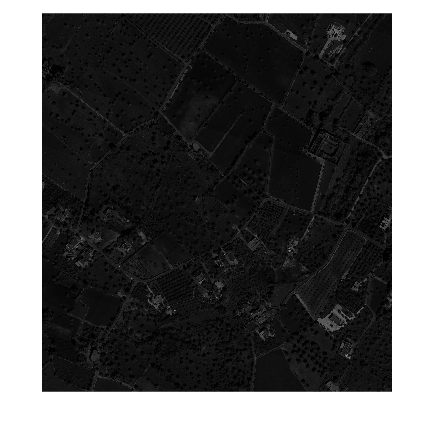

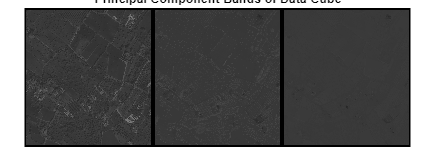

Replicate 1, 87 iterations, total sum of distances = 59874.5.


Best total sum of distances = 59867.9


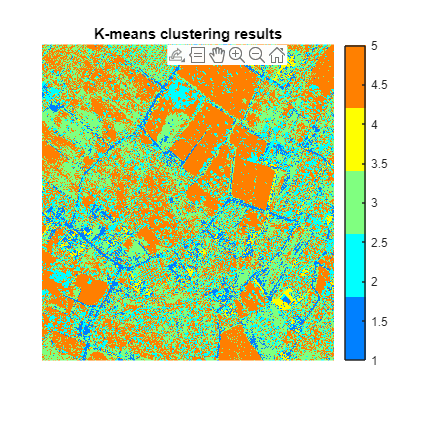

clc

clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);

% Calculating PCA
[image,components] = PCA(hcube,5);

% k-means clustering
num_clusters = 5;

% Reshaping image
pixels = reshape(image, [], size(image, 3));

opts = statset('Display','final','MaxIter',10000);
[idx, centers] = kmeans(pixels, num_clusters, 'Options', opts);

% Obtaining image's sizes
[rows, cols, ~] = size(image);

image = reshape(idx, [rows, cols]);

% Plot results
figure;
imshow(reshape(idx, [rows, cols]), []);
colormap(jet(num_clusters));
colorbar;
title('K-means clustering results');